clear

## **Lista de funções:**

r = @(x) 100*(x(2)-x(1)^2)^2 + (1-x(1))^2;
g = @(x) x(1)*(x(1) + 3)*(x(1) - 3)*(x(1) - 5) + x(2)*(x(2) + 3)*(x(2) - 3)*(x(2) - 5);
f = @(x) ((x(1))^2 - 100)*((x(1))^2 - 61) + ((x(2))^2 - 25)*((x(2))^2 - 16) - 15*cos(x(1)-(7/5))*cos(x(2)-(9/2));
h = @(x) ((x(1))^2 - 100)*((x(1))^2 - 61) + ((x(2))^2 - 25)*((x(2))^2 - 16) - 15*sin(x(1)-(7/5))*sin(x(2)-(9/2));

## Teste 1 - Função matemática g(x)

disp("--------------- Variaveis globais --------------");

--------------- Variaveis globais --------------


Nvar = 2;
Nmax = randi([35,50])

Nmax = 49

errodf = 15e-2

errodf = 0.1500

NPontosIniciais = randi([8,13])

NPontosIniciais = 10

x_values=[-11;-11]; y_values=[7;7];

disp("------------------- Outputs -------------------");

------------------- Outputs -------------------



PontosIniciais = getNPontosIniciais(NPontosIniciais, Nvar, x_values, y_values);
%Inicio timer
tic;
[Lista, LNit, Lopt, dffinal] = newton_raphson(g, Nmax, errodf, PontosIniciais, x_values, y_values);
tempo_execucao_teste1 = toc

tempo_execucao_teste1 = 1.9998

xopt_teste1 = minGlobal(Lopt, g)

xopt_teste1 =    -1.8706
   -1.8706


taxa_media_convergencia_teste1 = taxaMediaConvergencia(LNit)

taxa_media_convergencia_teste1 = 5.8000

tipo_convergencia_teste1 = tipoConvergencia(dffinal, errodf, Nmax)

tipo_convergencia_teste1 = 'Convergência para um mínimo global'

[minimos_locais_teste1, minimizantes_locais_teste1] = minimosMinimizantesLocais(Lopt, g)

minimos_locais_teste1 =    -1.8706
   -1.8706


minimizantes_locais_teste1 = -141.3956

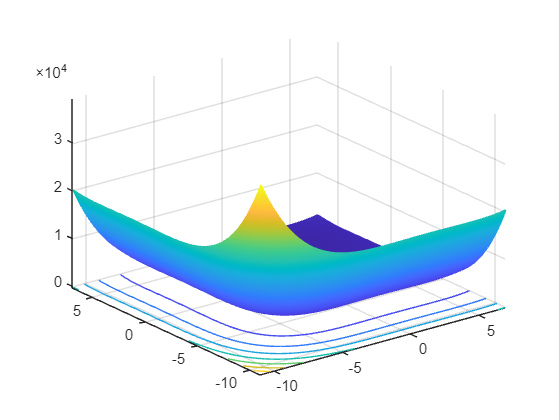

close all

nivelGraficos(g,x_values(1),y_values(1),x_values(2),y_values(2))

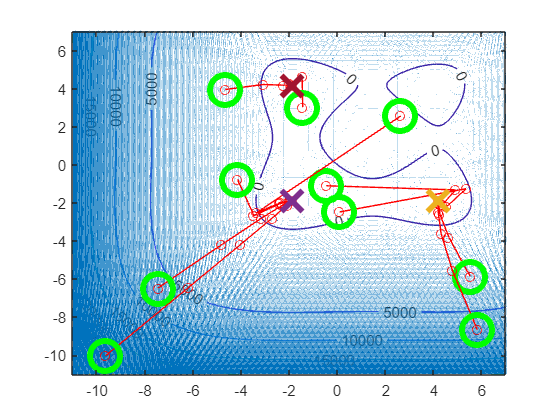


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off

## Teste 2- Função de Rosenbrock

disp("---------------------- // ----------------------")

---------------------- // ----------------------



tic;
[Lista, LNit, Lopt, dffinal] = newton_raphson(r, Nmax, errodf, PontosIniciais, x_values, y_values);
tempo_execucao_teste2 = toc

tempo_execucao_teste2 = 9.6423

xopt_teste2 = minGlobal(Lopt, r)

xopt_teste2 =     0.9989
    0.9978


taxa_media_convergencia_teste2 = taxaMediaConvergencia(LNit)

taxa_media_convergencia_teste2 = 28.3000

tipo_convergencia_teste2 = tipoConvergencia(dffinal, errodf, Nmax)

tipo_convergencia_teste2 = 'Convergência para um mínimo global'

[minimos_locais_teste2, minimizantes_locais_teste2] = minimosMinimizantesLocais(Lopt, f)

minimos_locais_teste2 =     0.9970    1.0023
    0.9941    1.0043


minimizantes_locais_teste2 = 1.0e+03 *

    6.3143    6.3119


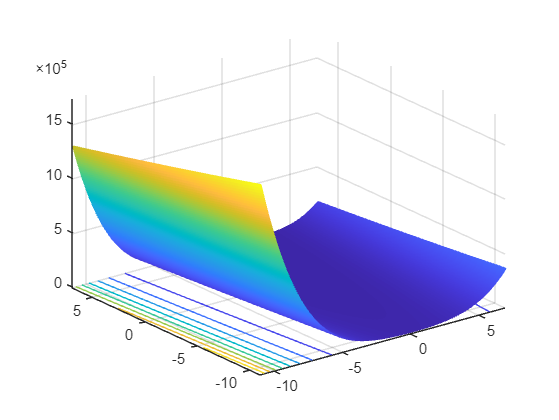

close all

nivelGraficos(r,x_values(1),y_values(1),x_values(2),y_values(2))

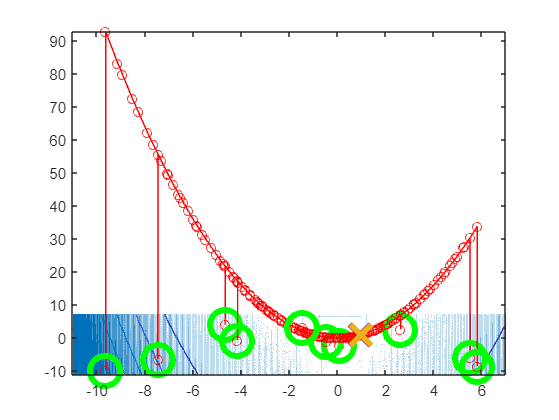


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off

## Teste 3- Função matemática f(x)

disp("---------------------- // ----------------------")

---------------------- // ----------------------



tic;
[Lista, LNit, Lopt, dffinal] = newton_raphson(f, Nmax, errodf, PontosIniciais, x_values, y_values);
tempo_execucao_teste3 = toc

tempo_execucao_teste3 = 7.4852

xopt_teste3 = minGlobal(Lopt, f)

xopt_teste3 =    -8.9548
   -4.5477


taxa_media_convergencia_teste3 = taxaMediaConvergencia(LNit)

taxa_media_convergencia_teste3 = 18.4000

tipo_convergencia_teste3 = tipoConvergencia(dffinal, errodf, Nmax)

tipo_convergencia_teste3 = 'Convergência para um mínimo global'

[minimos_locais_teste3, minimizantes_locais_teste3] = minimosMinimizantesLocais(Lopt, f)

minimos_locais_teste3 =     8.9499    8.9928   -8.9548
    4.5270   -4.5188   -4.5477


minimizantes_locais_teste3 =  -404.8301 -396.7978 -408.7072


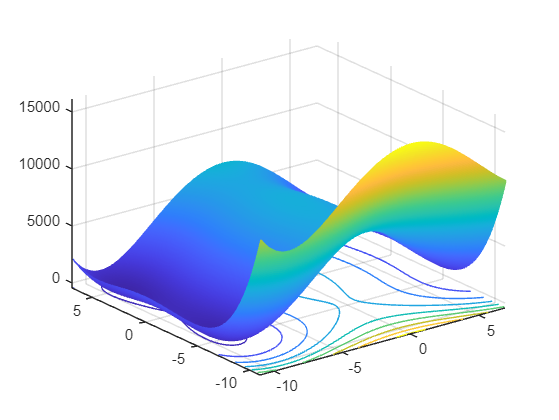

close all

nivelGraficos(f,x_values(1),y_values(1),x_values(2),y_values(2))

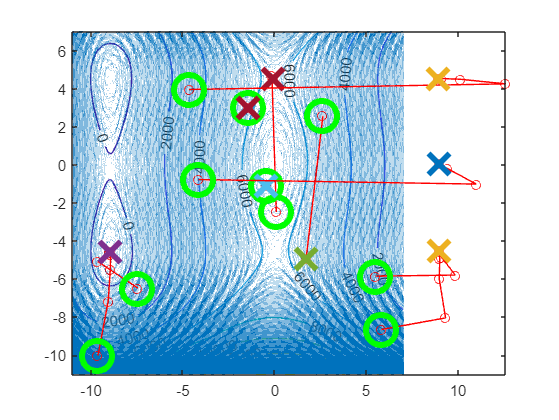


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off

## Teste 4 - Função matemática h(x,y)

disp("---------------------- // ----------------------")

---------------------- // ----------------------



tic;
[Lista, LNit, Lopt, dffinal] = newton_raphson(h, Nmax, errodf, PontosIniciais, x_values, y_values);
tempo_execucao_teste4 = toc

tempo_execucao_teste4 = 8.1676

xopt_teste4 = minGlobal(Lopt, h)

xopt_teste4 =     8.9729
    4.6126


taxa_media_convergencia_teste4 = taxaMediaConvergencia(LNit)

taxa_media_convergencia_teste4 = 22.9000

tipo_convergencia_teste4 = tipoConvergencia(dffinal, errodf, Nmax)

tipo_convergencia_teste4 = 'Convergência para um mínimo global'

[minimos_locais_teste4, minimizantes_locais_teste4] = minimosMinimizantesLocais(Lopt, f)

minimos_locais_teste4 =     8.9729    8.9702   -8.9678
    4.6126   -4.6091   -4.5963


minimizantes_locais_teste4 =  -404.0316 -395.9523 -408.4419


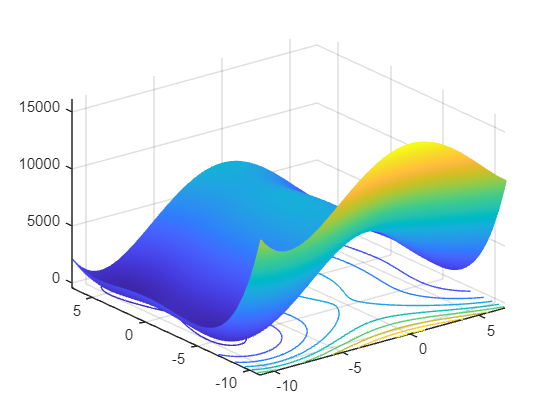

close all

nivelGraficos(h,x_values(1),y_values(1),x_values(2),y_values(2))

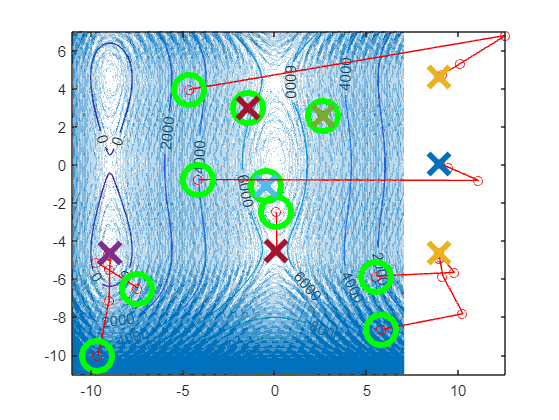


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off

T = table([tempo_execucao_teste1; tempo_execucao_teste2; tempo_execucao_teste3;tempo_execucao_teste4], ...
          [taxa_media_convergencia_teste1; taxa_media_convergencia_teste2; taxa_media_convergencia_teste3; taxa_media_convergencia_teste4], ...
          {tipo_convergencia_teste1; tipo_convergencia_teste2; tipo_convergencia_teste3; tipo_convergencia_teste4}, ...
          'VariableNames', {'Tempo de Execucao', 'Taxa Media de Convergencia', 'Tipo de Convergencia'}, ...
          'RowNames', {'Teste1', 'Teste2', 'Teste3', 'Teste4'});

disp(T);

              Tempo de Execucao    Taxa Media de Convergencia             Tipo de Convergencia         
              _________________    __________________________    ______________________________________

    Teste1         1.9998                      5.8               {'Convergência para um mínimo global'}
    Teste2         9.6423                     28.3               {'Convergência para um mínimo global'}
    Teste3         7.4852                     18.4               {'Convergência para um mínimo global'}
    Teste4         8.1676                     22.9               {'Convergência para um mínimo global'}

